 % MPPT Algorithms Demonstration
% Author: Trinadh Ramanjaneyulu Kola

clc; clear; close all;

% --- Parameters ---
V = linspace(0, 40, 200);    % Voltage sweep
I = 8 - 0.2*V;               % Example IV curve (linear approx)
I(I<0) = 0;                  % Avoid negative current
P = V .* I;                   % Power

% --- Perturb & Observe (P&O) Algorithm ---
dV = 0.5;          % Step size
Vref = 20;         % Initial reference

for k = 1:50
    Vold = Vref;
    Pold = Vold * interp1(V,I,Vold);
    Vnew = Vref + dV;
    Pnew = Vnew * interp1(V,I,Vnew);

    if Pnew > Pold
        Vref = Vnew;
    else
        dV = -dV; % reverse direction
    end
end
MPP_PO = Vref;
disp(['P&O MPP Voltage = ', num2str(MPP_PO)]);

P&O MPP Voltage = 20



% --- Incremental Conductance (INC) Algorithm ---
for k = 2:length(V)
    dI = I(k) - I(k-1);
    dV2 = V(k) - V(k-1);
    if dV2 ~= 0 && abs(dI/dV2 + I(k)/V(k)) < 0.01
        MPP_INC = V(k);
        break;
    end
end
disp(['INC MPP Voltage = ', num2str(MPP_INC)]);

INC MPP Voltage = 19.6985


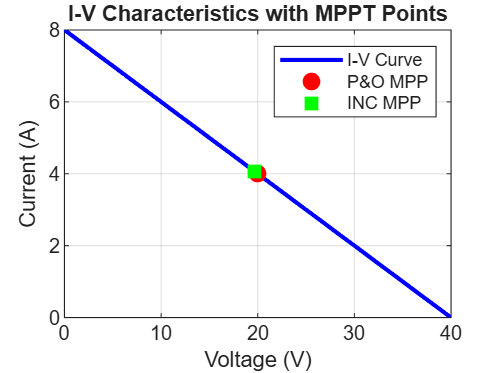


% --- Plot I-V Curve ---
figure;
plot(V,I,'b','LineWidth',2); grid on; hold on;
plot(MPP_PO,interp1(V,I,MPP_PO),'ro','MarkerSize',8,'MarkerFaceColor','r');
plot(MPP_INC,interp1(V,I,MPP_INC),'gs','MarkerSize',8,'MarkerFaceColor','g');
xlabel('Voltage (V)');
ylabel('Current (A)');
title('I-V Characteristics with MPPT Points');
legend('I-V Curve','P&O MPP','INC MPP');

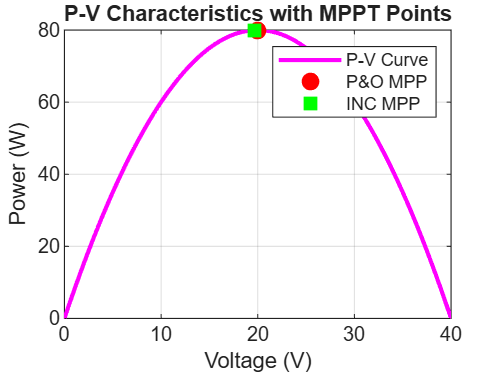


% --- Plot P-V Curve ---
figure;
plot(V,P,'m','LineWidth',2); grid on; hold on;
plot(MPP_PO,MPP_PO*interp1(V,I,MPP_PO),'ro','MarkerSize',8,'MarkerFaceColor','r');
plot(MPP_INC,MPP_INC*interp1(V,I,MPP_INC),'gs','MarkerSize',8,'MarkerFaceColor','g');
xlabel('Voltage (V)');
ylabel('Power (W)');
title('P-V Characteristics with MPPT Points');
legend('P-V Curve','P&O MPP','INC MPP');